## **Backward TRF example**

This example script loads and preprocesses a publicly available electroencephalography (EEG) dataset (the Natural Speech dataset, [https://www.cell.com/current-biology/fulltext/S0960-9822(15)01001-5](https://www.cell.com/current-biology/fulltext/S0960-9822(15)01001-5), [https://www.cell.com/current-biology/fulltext/S0960-9822(18)30146-5?5952eaf7=ef28a21f](https://www.cell.com/current-biology/fulltext/S0960-9822(18)30146-5?5952eaf7=ef28a21f)[,](https://doi.org/10.7554/eLife.51784,) [https://datadryad.org/stash/dataset/doi:10.5061/dryad.070jc](https://datadryad.org/stash/dataset/doi:10.5061/dryad.070jc)). The same script can be applied to other datasets (see the list of datasets here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html)). EEG signals were recorded as participants listened to monophonic Bach melodies.

'dataStim.mat' contains the stimulus features. 'pre_dataSub1.mat' contains the preprocessed EEG signals (see [https://pubmed.ncbi.nlm.nih.gov/37744463/](https://pubmed.ncbi.nlm.nih.gov/37744463/)). Then, the script runs a typical forward TRF analysis to measure how strongly the EEG signals encode specific stimulus features, such as the sound envelope and the note onsets.

Note: Please see [https://cnspworkshop.net](https://cnspworkshop.net) and [https://diliberg.net](https://diliberg.net) for additional resources such as tutorials, videotutorials, and datasets.

Author: Giovanni M. Di Liberto ([https://diliberg.net](https://diliberg.net)) 

Please cite:

- mTRF-Toolbok: [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full) 

- Open science framework: [https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli](https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli) 

Please check out

- mTRF-Toolbox - Considerations for applied research: [https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full](https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full) 

- Original study for the Natural Speech dataset: [https://www.cell.com/current-biology/fulltext/S0960-9822(15)01001-5](https://www.cell.com/current-biology/fulltext/S0960-9822(15)01001-5)

- Follow up study with recordings from additional nine individuals: [https://www.cell.com/current-biology/fulltext/S0960-9822(18)30146-5?5952eaf7=ef28a21f](https://www.cell.com/current-biology/fulltext/S0960-9822(18)30146-5?5952eaf7=ef28a21f) 

- CND dataset available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) 

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear all
close all

addpath ./libs/cnsp_utils
addpath ./libs/cnsp_utils/cnd
addpath ../mtrf
addpath ./libs/fileDownload

disp('Backward TRF example live-script')

Backward TRF example live-script


### Data preparation

This section downloads the sample data. This sample dataset consists of 64-channel EEG time-series from two distinct individuals (pre_dataSub files; note that the original dataset includes data from 20 participants). The signals were filtered between 1 and 8 Hz and downsampled to 64Hz. The dataStim.mat file contains features of the corresponding music stimulus (i.e., Hilbert envelope and note onsets). dataStim is the input of a forward mTRF model. dataSub is the output of a forward mTRF model.

Note that the following section (the data loader) is almost identical to the other example scripts. The only difference is the name of the sample dataset 'datasetName'.

% Sample data from "LalorNatSpeech" dataset
datasetName = "LalorNatSpeech";

% Creating directory where the sample data will be downloaded
if ~exist(datasetName, 'dir')
    mkdir(datasetName)
end

% Setting up filenames and URL
stimFilename = "dataStim.mat";
eegFilenames = {'pre_dataSub1.mat','pre_dataSub2.mat'};

dataStim_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+stimFilename;

% Download stimulus file
if ~isfile(datasetName+"/"+stimFilename)
    downloadFile(datasetName+"/"+"dataStim.mat", dataStim_URL, ShowFilename=true)
else
    disp('Skipping download. Stim file already present.')
end

Skipping download. Stim file already present.



% Download neural data file
for iiSub = 1:length(eegFilenames)
    dataSub_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+eegFilenames{iiSub};

    if ~isfile(datasetName+"/"+eegFilenames{iiSub})
        downloadFile(datasetName+"/"+eegFilenames{iiSub}, dataSub_URL, ShowFilename=true)
    else
        disp('Skipping download. EEG file already present.')
    end

end

Skipping download. EEG file already present.
Skipping download. EEG file already present.
Skipping download. EEG file already present.


 
nSubs = length(eegFilenames);

### Backward TRF model fit

Setting up mTRF hyperparameters

tmin = -200;
tmax = 600;
lambdas = 10.^(-4:2:4); % small set of lambdas (quick)
% lambdas = 10.^(-6:1:6); % larger set of lambdas (slower)
dirTRF = -1; % Backward TRF model
stimIdx = 1; % Stimulus feature to use in the model fit

if tmin > tmax
    disp('Warning: tmin > tmax; setting tmax=tmin for the analysis')
    tmax = tmin;
end

Loading Stimulus data

stimFilename = datasetName+"/"+"dataStim.mat";
load(stimFilename,'stim')

stim = cndNormalise(stim);

Loading EEG data

subIdx = 1;
eegFilename = datasetName+"/"+eegFilenames{subIdx}; 
load(eegFilename,'eeg')

eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length. The trial may end a few seconds after the end of the audio e.g., the neural data may include the break between trials. It would be best to do this chunking at preprocessing, but let's check here, just to be sure. The function returnes a version of stim and eeg where their lengths have been made equal by cutting the tail of the longer time-series where necessary.

% Downsampling stim if necessary
if eeg.fs < stim.fs
    stim = cndDownsample(stim, eeg.fs);
end

Processing CND: Downsampling from fs = 128 to downFs = 64



[stim,eeg] = cndCheckStimNeural(stim,eeg);

### Backward TRF

Determine optimal lambda

% Reducing the number of electrodes to make this example faster
eeg.data = cellfun(@(x) x(:,1:8:end),eeg.data,'UniformOutput',false);

[stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
    
% Calculating optimal lambda. Display and store results
[maxR,bestLambda] = max(squeeze(mean(stats.r,1))); % mean across trials
disp(['r = ',num2str(maxR)])

r = 0.094478


rAll(subIdx) = maxR;
disp(['Mean r = ',num2str(mean(rAll))])

Mean r = 0.094478


'stats.r' contains the envelope reconstruction correlations for all the trials and lambdas (20x5, in this case).

Let's have a look at the tuning curve:

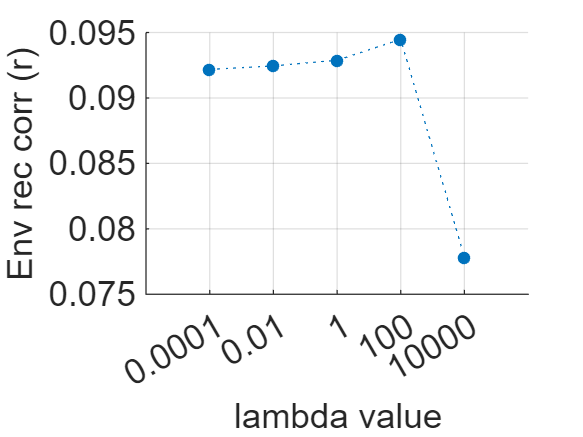

figure;
plot(mean(stats.r,1),'.:','MarkerSize',15)
xlabel('lambda value')
xticks(1:length(lambdas))
xticklabels(lambdas)
ylabel('Env rec corr (r)')
run prepExport.m % beautify the plot
grid on

So, lambda 100 is optimal for this participant. Let's have a look at the correlation values across trials (segments of EEG data) for the optimal lambda:

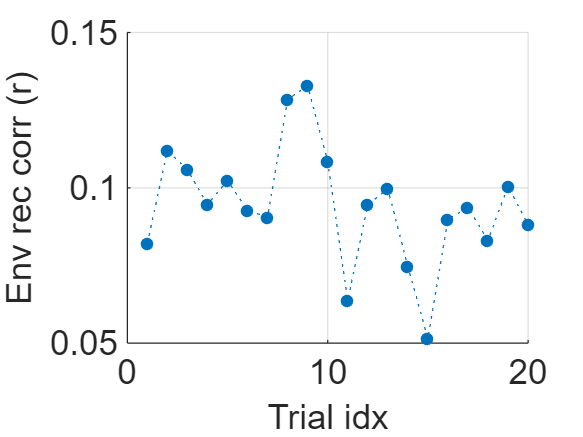

figure;
plot(stats.r(:,bestLambda),'.:','MarkerSize',15)
xlabel('Trial idx')
ylabel('Env rec corr (r)')
run prepExport.m % beautify the plot
grid on

So the Envelope reconstruction correlations range quite a lot, from about 0.01 to 0.07. That is expected with EEG data. Note that this fluctuation depends on the trial length (i.e., typically smaller fluctuations when considering longer trials). So, depending on the design of the experiment, such fluctuation might be meaningful or purely due to noise.

Let's also have a look at the actual envelope reconstruction. Let's select a test fold for the reconstruction:

testTr = 1;
trainTr = 2:length(eeg.data);

model = mTRFtrain(stim.data(stimIdx,trainTr),eeg.data(trainTr),eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);

[pred,stats] = mTRFpredict(stim.data(stimIdx,testTr),eeg.data(testTr),model);


Test on 11365 samples
Predicting output
1/1 [=] - 0.163s/fold
correlation: 0.0821 - error: 1.0066


And plot the first 5 seconds of envelope!

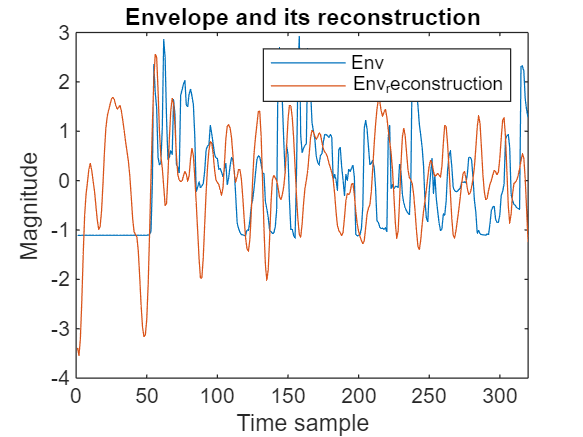

t2plot = 1:eeg.fs*5;
figure;
plot(zscore(stim.data{stimIdx,testTr}(t2plot)))
hold on
plot(zscore(pred(t2plot)))
xlabel('Time sample')
ylabel('Magnitude')
title('Envelope and its reconstruction')
legend({'Env','Env_reconstruction'})

Let's go back to the crossvalidation now, and run it on participants 1 and 2:

for subIdx = 1:2
    eegFilename = datasetName+"/"+eegFilenames{subIdx}; 
    load(eegFilename,'eeg')
    
    eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

    % Downsampling stim if necessary
    if eeg.fs < stim.fs
        stim = cndDownsample(stim, eeg.fs);
    end
    
    [stim,eeg] = cndCheckStimNeural(stim,eeg);
    
    % Reducing the number of electrodes to make this example faster
    eeg.data = cellfun(@(x) x(:,1:8,end),eeg.data,'UniformOutput',false);
    
    [stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
        
    % Calculating optimal lambda. Display and store results
    [maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
    disp("Participant "+subIdx+" r = "+num2str(maxR))
    rAll(subIdx) = maxR;
    % disp(['Mean r = ',num2str(mean(rAll))])

end

Participant 1 r = 0.049741
Participant 2 r = 0.032672


Plot the envelope reconstruction correlations for the two participants

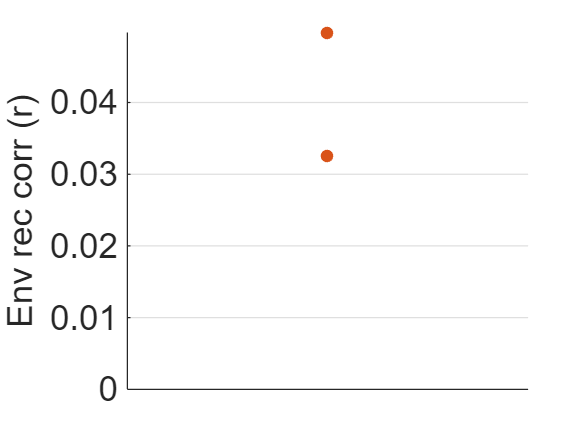

figure;
plot(ones(length(rAll)), rAll,'.','MarkerSize',15)
ylim([min(0,min(rAll)),max(rAll)])
xticks([])
ylabel("Env rec corr (r)")
grid on
run prepExport.m